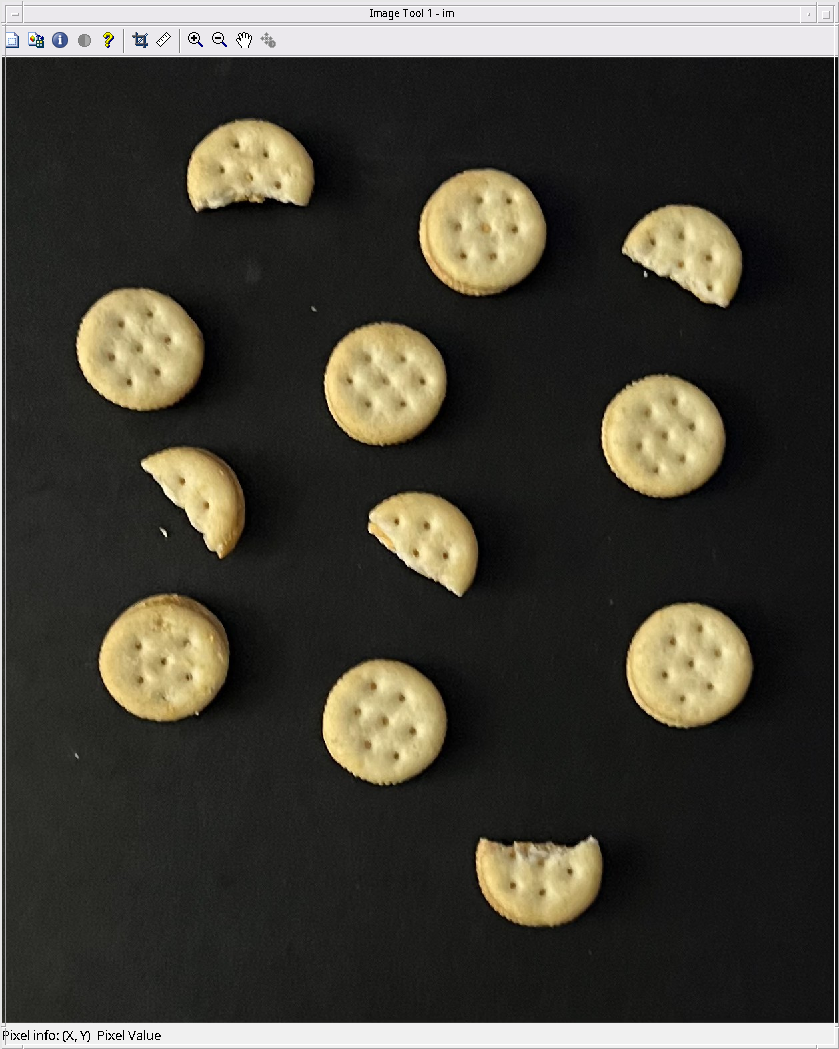

B = 12×1 cell array
    {529×2 double}
    {545×2 double}
    {431×2 double}
    {514×2 double}
    {528×2 double}
    {523×2 double}
    {436×2 double}
    {536×2 double}
    {523×2 double}
    {523×2 double}
    {459×2 double}
    {532×2 double}


L =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

boundary =    419   115
   418   116
   417   117
   416   117
   415   117
   414   117
   413   117
   412   117
   411   117
   410   117


metric = 0.9055

boundary =    903   148
   902   149
   901   149
   900   149
   899   149
   898   149
   897   149
   896   149
   895   149
   894   150


metric = 0.9004

boundary =    606   212
   605   213
   604   214
   603   214
   602   215
   602   216
   602   217
   602   218
   602   219
   601   220


metric = 0.6924

boundary =    175   281
   174   282
   173   282
   172   282
   171   282
   170   282
   169   282
   168   282
   167   282
   166   282


metric = 0.7643

boundary =         1002         484
        1001         485
        1000         485
         999         485
         998         485
         997         485
         996         485
         995         485
         994         485
         993         485


metric = 0.8967

boundary =    487   486
   486   487
   485   487
   484   487
   483   487
   482   487
   481   487
   480   487
   479   487
   478   487


metric = 0.8935

boundary =    706   552
   705   553
   704   553
   703   553
   702   553
   701   553
   700   553
   699   553
   698   553
   697   554


metric = 0.7711

boundary =    261   628
   260   629
   259   629
   258   629
   257   629
   256   629
   255   629
   254   629
   253   629
   252   629


metric = 0.9008

boundary =         1193         713
        1192         714
        1191         715
        1190         715
        1189         715
        1188         715
        1187         715
        1186         715
        1185         716
        1184         716


metric = 0.7403

boundary =    556   902
   555   903
   554   903
   553   903
   552   903
   551   903
   550   903
   549   903
   548   903
   547   903


metric = 0.8976

boundary =    286   933
   285   934
   284   934
   283   935
   282   935
   281   936
   280   936
   279   936
   278   936
   277   937


metric = 0.7702

boundary =    912   939
   911   940
   910   940
   909   940
   908   940
   907   940
   906   940
   905   940
   904   940
   903   940


metric = 0.8983

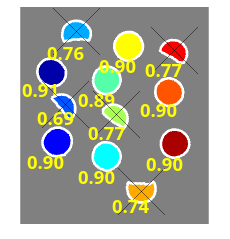

ans = "Total Cookies: 12"

ans = "Total DEFECTIVE Cookies: 5"

ans = "Total INTACT Cookies: 7"

% Importing cookie images 

im_1 = imread('/home/aaron/Pictures/cookies_2.jpg');

processCookies(im_1, .85, .2)


% importing function from previous lab 
function [total_objects, round_objects] = processCookies(im, roundness_threshold, graypoint)
    % display original image 
   imtool(im);
   
    % converting to grayscale 
    im_gray = rgb2gray(im);
    
    
    % binarizing the image (passing -1 lets us have the default algorithm choose the gray point)
    if graypoint == -1
        graypoint = graythresh(im_gray);
    end
    
    im_bin_threshold = imbinarize(im_gray, graypoint); % removes objects 
    
    % removing noise/grains 
    im_bin_denoise = bwareaopen(im_bin_threshold, 1000); % lots of tweaking 
    
    % filling in any holes in the image 
    se = strel('disk', 20); % lots of tweaking 
    im_bin_closed = imclose(im_bin_denoise, se); 
    im_bin_filled = imfill(im_bin_closed, 'holes');

    
    % Boundary and Label Matrices 
    [B, L] = bwboundaries(im_bin_filled, 'noholes')
    imshow(label2rgb(L, @jet, [.5 .5 .5])) % Displaying the distinct objects 
    
   
    
     % getting true and circular areas 
     stats = regionprops(L, 'Area', 'Centroid');
    
     % counting round objects (those that are above threshold value)
     objects_exceed_threshold = 0; 

      % appending more data to the graph 
    hold on 
  
    
    % drawing boundaries
    for k = 1 : length(B)
	    boundary = B{k}
	    plot(boundary(:,2), boundary(:,1), 'w', 'LineWidth', 2)
        
        delta_sq = diff(boundary).^2; 
        perimeter = sum(sqrt(sum(delta_sq,2))); 
    
        area1 = perimeter^2/(4*pi);
        area2 = stats(k).Area;
        
        area_true = stats(k).Area;
        metric = area2/area1
        
        metric_string = sprintf("%2.2f",metric);
        
        % plot a circle about the centroid 
        if metric < roundness_threshold 
	        centroid = stats(k).Centroid; 
            objects_exceed_threshold = objects_exceed_threshold + 1;
	        plot(centroid(1), centroid(2), 'KX', 'MarkerSize', 50);
        end 


    
        % plot the roundness or ciruclarity metric near the object 
        text(boundary(1,2)-100, boundary(1,1)+120, metric_string, 'color', 'y','FontSize', 14, 'FontWeight', 'bold'); 
    end 
    
     hold off

    sprintf("Total Cookies: %.f", length(B))
    sprintf("Total DEFECTIVE Cookies: %.f", objects_exceed_threshold)
    sprintf("Total INTACT Cookies: %.f", (length(B) - objects_exceed_threshold))
    
end
